clear; close;

## Harrison Robel; Partner: Karen Kong

## Lab 2: Convolutions

## Problem 1: Fermi Telescope

Convoluting is a strong tool that we will be exploring in this lab that is used for combining PDFs. A convolution is where you move two functions or discrete datasets across each other in oposite directions and integrate the area beneth the two functions. In terms of math the discrete form is $P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)P_B \left(x-z\right)$ and in continous form is $P_{A+B} \left(x\right)=\int P_A \left(z\right)P_B \left(x-z\right)\textrm{dz}$ which are both denoted by $P_A \left(x\right)\ast P_{B\left(\right.} \left(x\right)$ where the star means convolution. 

An example of where a convolution becomes use full is when measuring a background over several days/events. In this case we will study the Fermi Telescope. When looking for gamma-ray sources in the galaxy there is a background of cosmic rays that create a discrete Poisson distribution. When getting signals from outer space it is neccessary to determine the probability that the signal could have come from the background. 

The width of the Poisson distribution for the background in this problem will be X = 1 with Y = 2 counts of gamma rays from the source.

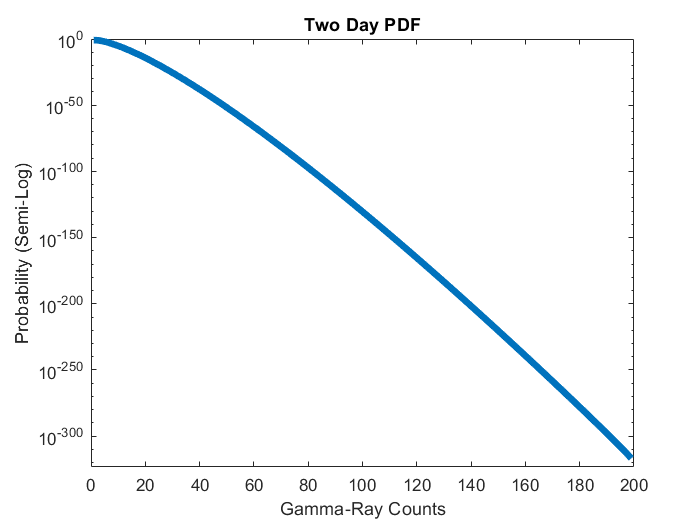

X = 1;
x = 1:100;
P1 = poisspdf(x,X);

D2 = conv(P1,P1);
plot(D2,"LineWidth",4)
set(gca,'YScale','log')
title('Two Day PDF')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)') 

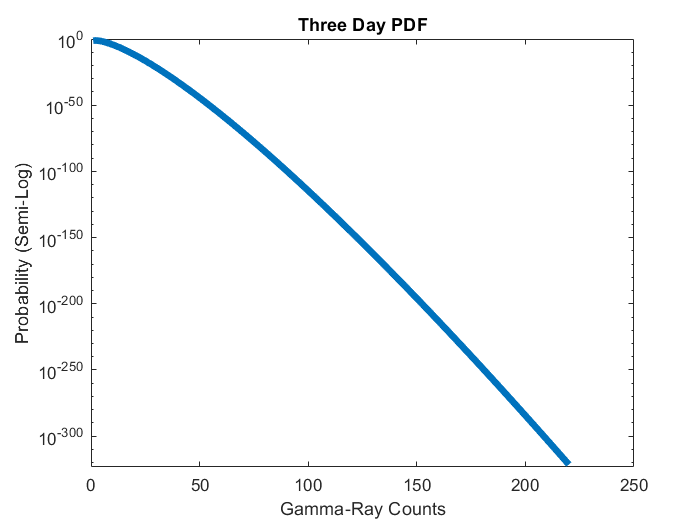

D3 = conv(D2,P1);
plot(D3,"LineWidth",4)
set(gca,'YScale','log')
title('Three Day PDF')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

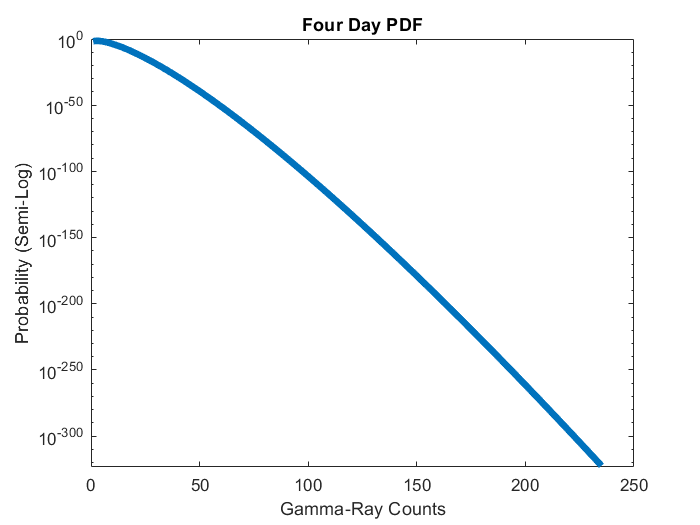

D4 = conv(D3,P1);
plot(D4,"LineWidth",4)
set(gca,'YScale','log')
title('Four Day PDF')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

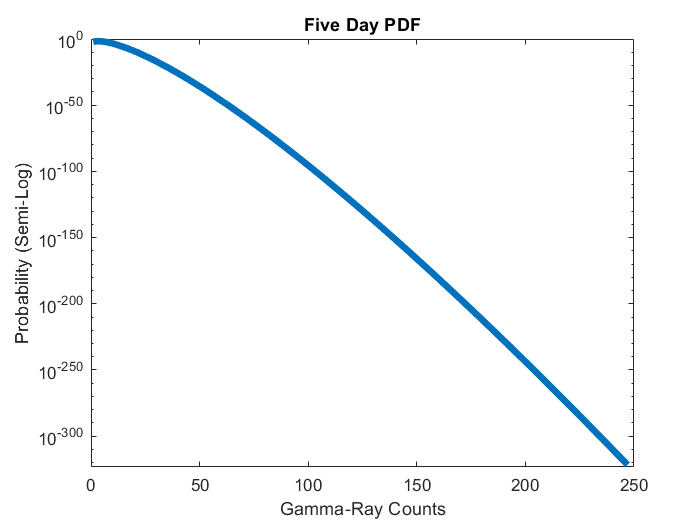

D5 = conv(D4,P1);
plot(D5,"LineWidth",4)
set(gca,'YScale','log')
title('Five Day PDF')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

Above are several graphs each with another day of background noise convoluted onto the previous graph. As you sum the graphs the graphs remain as a Poisson distribution but the width of the graph starts to increase. The width of the graph becomes the same as if you were to create a distribution with a sigma value X equal to n times the orignal X (nX) where n is the number of times you added (convoluted) another distribution. This is not always the case, but works out because each distribution is the same distribution as the previous ones. Conceptually this makes sense because adding a Poisson distribution with another Poisson distribution should logically give another Poisson distribution. Mathematically because addition is a linear opperation when two function add it adds their parameters. 

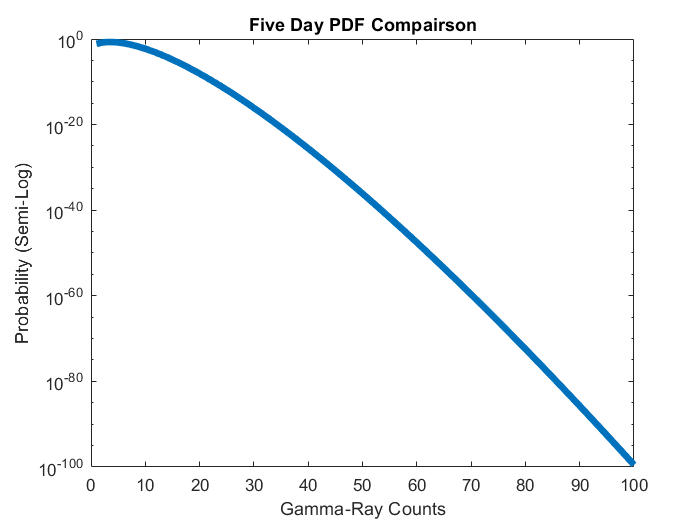

Test = poisspdf(x,X*4);
plot(Test,"LineWidth",4)
set(gca,'YScale','log')
title('Five Day PDF Compairson')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

The graph above is Poisson distribution with (nX) where n=4 because the PDFs were convoluted four times. 

To take an average normally you divide the values of the Y-axis by the sum of how many compents there are. For taking the average of a convolution you need to scale down the X-axis by the number of convolutions. This creates an effect where the more that you convolute the function and take the average the narrower the PDF becomes. This acts as a weighted or moving average and is used to smooth out data when the data has a lot of noise.

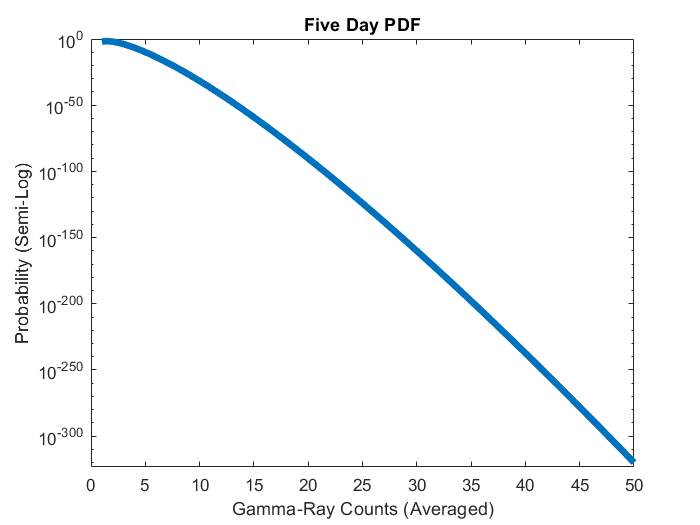

cx = 1:(1/5):100;
plot(cx,D5,"LineWidth",4);
set(gca,'YScale','log')
title('Five Day PDF')
xlabel('Gamma-Ray Counts (Averaged)') 
ylabel('Probability (Semi-Log)')

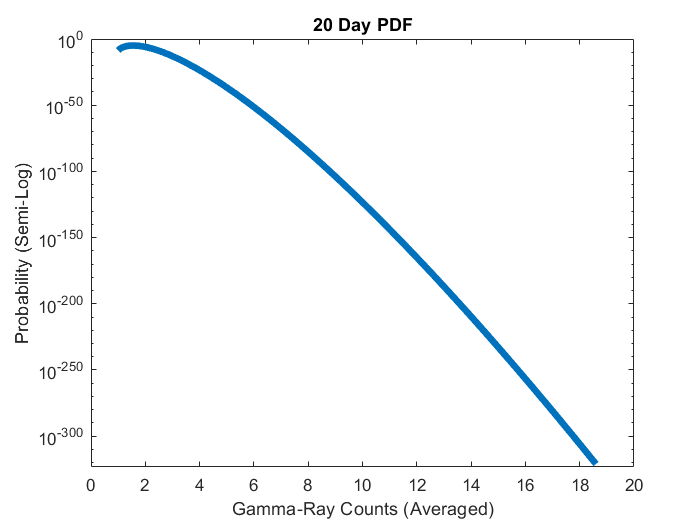


D10 = conv(D5,D5);
D20 = conv(D10,D10);

cx = 1:(1/20):100;
plot(cx,D20,"LineWidth",4);
set(gca,'YScale','log')
title('20 Day PDF')
xlabel('Gamma-Ray Counts (Averaged)') 
ylabel('Probability (Semi-Log)')

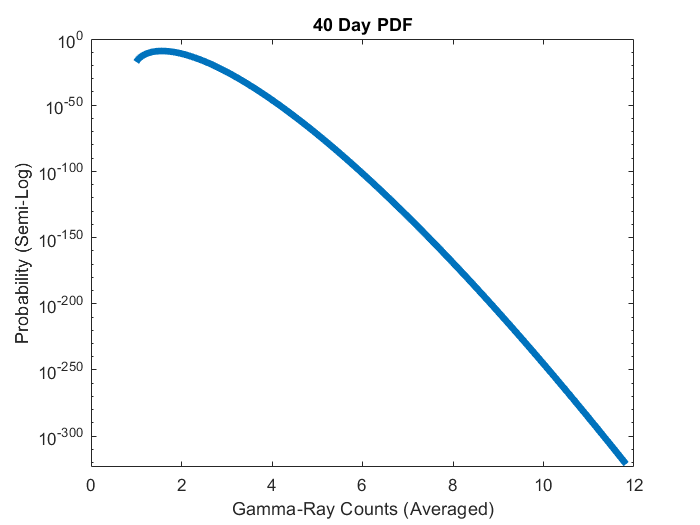


D40 = conv(D20,D20);

cx = 1:(1/40):100;
plot(cx,D40,"LineWidth",4);
set(gca,'YScale','log')
title('40 Day PDF')
xlabel('Gamma-Ray Counts (Averaged)') 
ylabel('Probability (Semi-Log)')

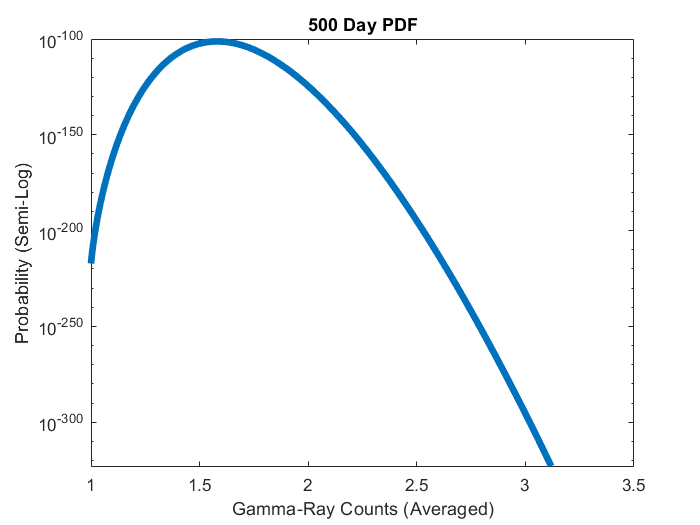


P1 = poisspdf(1:100,1);
Dt = P1;
for t = 1:499
    Dt = conv(Dt,P1);
end

cx = 1:(1/500):100;
plot(cx,Dt,"lineWidth",4)
set(gca,'Yscale','log')
title('500 Day PDF')
xlabel('Gamma-Ray Counts (Averaged)') 
ylabel('Probability (Semi-Log)')

The graphs above are all graphs of the average PDF functions. After many iterations the graph becomes more and more skewed towards the middle. The Central Limit Theorem states that given a data set of independent random distributions then the convolutions of the PDF will tend towards a normal distribution after many iterations and being properly normalized. You can see that after 500 iterations the graph is already looking fairly Gaussian.

N = 10;
Y = 2;
T = Y*N;

X1 = poisscdf(T,N,"upper")

X1 = 0.0016

Z1 = norminv(X1,N)

Z1 = 7.0499

To really test the significance of the signal we want to test the significance of the signal over several days. We can convolute the background distribution to get a PDF over mulitple days. Then take the probability that the background could create a signal that is as signal like or more than the event in question. Convert this into a sigma and determine if the signal is significant. The sigma for this probability is fairly high, above 5 sigma is considered significant therefore a 7 sigma is very significant. This makes sense because with 10 days of probabilites the odds of recieving the same signal over that span of times is very low.

## Problem 2: Chi-Squared Distribution

To convolute and sum distributions it does not have to be a Gaussian distribution and can also be continuous. A skewed distribution such as the Chi-Sqaured distribution works as well. 

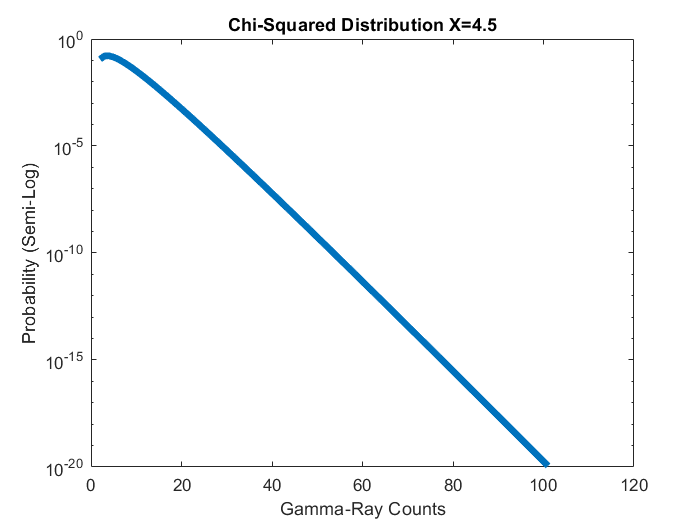

x = 0:100;
X1 = chi2pdf(x,4.5);

cx = 1:101;
plot(cx,X1,"lineWidth",4)
set(gca,'Yscale','log')
title('Chi-Squared Distribution X=4.5')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

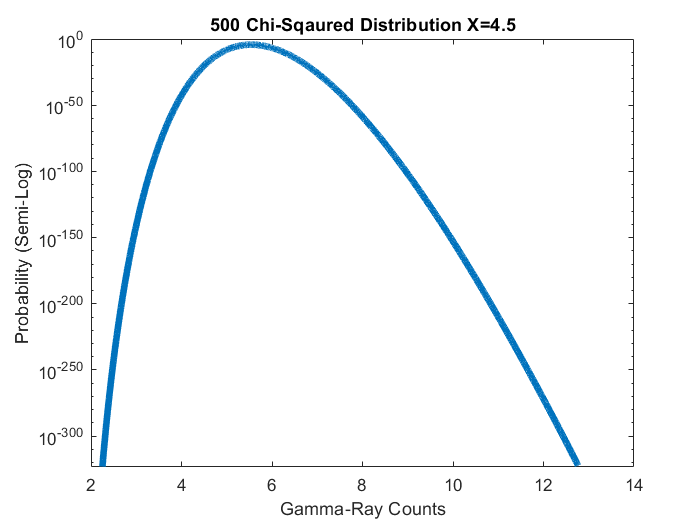


Xn = X1;
for n = 1:499
    Xn = conv(Xn,X1);
end

cx = 1:(1/500):101;
plot(cx,Xn,"lineWidth",4)
set(gca,'Yscale','log')
title('500 Chi-Sqaured Distribution X=4.5')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

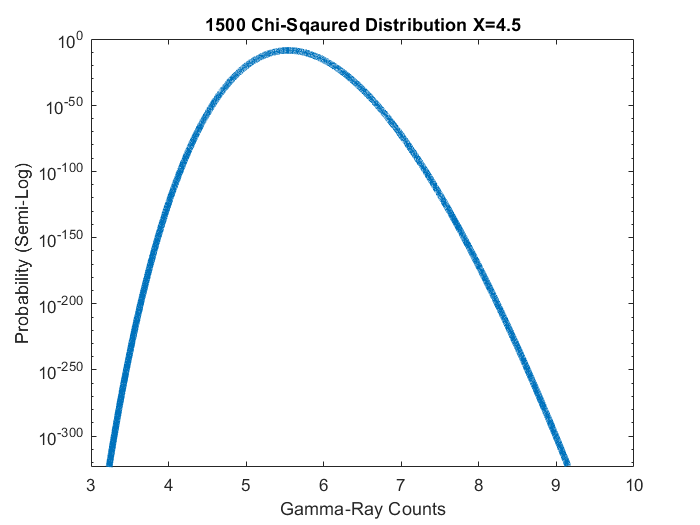


Xn = X1;
for n = 1:1499
    Xn = conv(Xn,X1);
end

cx = 1:(1/1500):101;
plot(cx,Xn,"lineWidth",4)
set(gca,'Yscale','log')
title('1500 Chi-Sqaured Distribution X=4.5')
xlabel('Gamma-Ray Counts') 
ylabel('Probability (Semi-Log)')

As you convolute the Chi-square distribution it starts to also approach a Gaussian. The outline of a Gaussian starts to appear around the order of magnitude of ~500 convolutions. After 1000+ iterations it becomes more clear that we have a Gaussian distribution that is slightly skewed towards one direction. 

## Problem 3: CCDs

Another form of telescopes where background noise needs to be sifted through are optical CCDs such as SWIFT. In optical sensors the background is a zero-mean Guassian distribution with constant width over the image. When we know where some point of interest is we can point the telescope at the event and take much more accurate data. One pixel detects the even while the rest of the pixels in the image can be used to determine the background width, in this case X = 1 and signal Y = 5.43. The signal is not a count but a floating point because the telescope is not sensitive enough. 

Signal = 5.43;
Width = 1;
% logN = makedist("Normal",'mu',0,'sigma',Width);
Dist = normpdf(-5:5,0,Width);
PD1 = normcdf(Signal,0,Width)

PD1 = 1.0000

SIGMA = norminv(PD1,0,Width)

SIGMA = 5.4300

From the sigma measure from the event studied we can claim a discovery because the sigma value is above the accepted value of 5.

It is important to know where to look. Without another satelites help we know the general area of where to point SWIFT but we do not know what pixel to study specifically. We can create a background and scan all pixels by convoluting together the background noise from all 10k pixels and average out the PDF function. The statistical question we are trying to answer is: Given the general region to look at what is the probability that an event that is signal like or more was caused by the background noise over all 10k pixels in the SWIFT telescope?

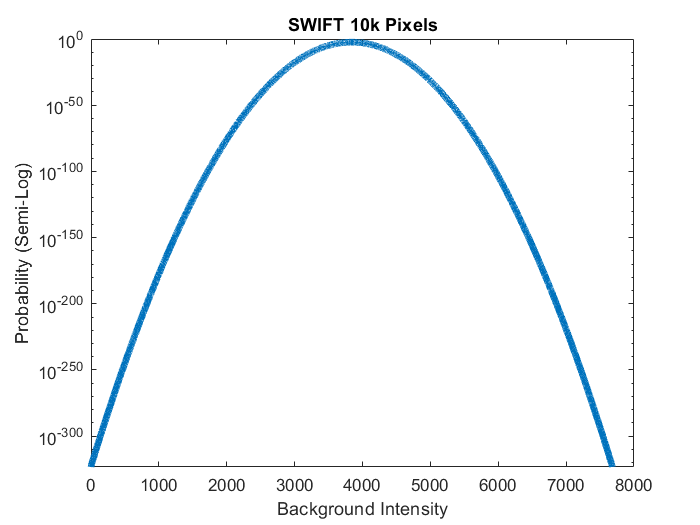

Prob = Dist;
Prob = Prob / sum(Prob);
Total = Prob;
for i = 1:10000
    Total = conv(Total,Prob);
end
Total = nonzeros(Total);

plot(Total,'linewidth',4)
set(gca,'Yscale','log')
title('SWIFT 10k Pixels')
xlabel('Background Intensity') 
ylabel('Probability (Semi-Log)')



sel = Signal*10^3:7679;
PD10k =  sum(Total(sel))

PD10k = 3.4713e-57

sigma10K = norminv(PD10k,0,10000*Width)

sigma10K = -1.5894e+05

From the result of sigma above we can see that we have a very low chance of making a discovery. This is because the odds that one pixel detects a spike in the background noise is very high. This is called the Look-Elsewhere effect or the trials factor. The effect is where a significant observation most likely occured because of the large amount of parameter space to be searched instead of an actual event. In this example one detection over 10k pixels is not significant.

## Problem 4: Trials Factor

To observe the importance of the Look-Elsewhere effect we can do the reverse of the process to find how many counts we would need to consitute a discovery in both the single pixel case and the 10k pixel case.

prob5 = normcdf(5);
probless = 1 - prob5;

Ndist = normrnd(0,Width,10000);
signal1 = find(Ndist > probless);
count1 = signal1(1)

count1 = 1

In the case were we know where to look we only need on the magnitude of 1-10 counts to be significant varrying depending on our background distribution.

signal10k = find(Total > probless);
count10k = signal10k(1)

count10k = 3404

For the 10k pixels we would need somewhere in the thousands of counts in order to be considered significant. This shows how important it is to know where to look or even just narrow do where to look to a smaller area and demostrates the Look-Elsewhere effect. The signal needs to be 1000x-2000x times brighter in order to be considered a discovery with 10k pixels.

Signal1k = 1.5;
Totalalot = Prob;
for n = 1:1000
    Totalalot = conv(Totalalot,Prob);
end
Totalalot = nonzeros(Totalalot);

selalot = Signal1k*10^3:2433;
PD1k = sum(Totalalot(selalot))

PD1k = 2.1427e-19

sigma1k = norminv(PD1k,0,1000*Width)

sigma1k = -8.9293e+03

Changing from a trials factor of 10k to 1k the sigma is still fairly poor but is several order of magnitude better than with 10k, showing that if you can narrow down your search you can increase your confidence.